  % Jeżeli nie zainstalowane: Control System Toolbox, Symbolic Math Toolbox
% Zad. 1
clear all;
p=[-0.5+9.5j,-0.5-9.5j,-1+10j,-1-10j,-0.5+10.5j,-0.5-10.5j];
z=[5j,-5j,15j,-15j];
p_real = real(p);
p_imag = imag(p);
z_real = real(z);
z_imag = imag(z);

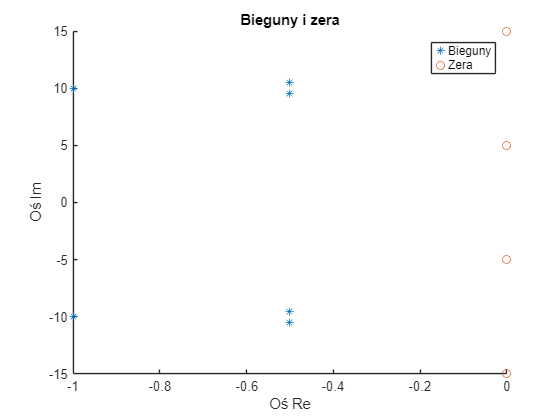

figure
% Create scatter of p_real and p_imag
scatter(p_real,p_imag,"Marker","*","DisplayName","p_imag");

hold on
% Create scatter of z_real and z_imag
scatter(z_real,z_imag,"Marker","o","DisplayName","z_imag");
hold off

legend

legend(["Bieguny","Zera"])
title("Bieguny i zera")
xlabel("Oś Re")
ylabel("Oś Im")

ba=0.426; % hardcoded for 1 units / 0 dB response at 10 rad/s
syms H(w)
H(w)=ba*(prod(1j*w-z)/prod(1j*w-p));
if true
    radianFreq = -50:0.1:50; %#ok<*UNRCH> 
else
    radianFreq = 7.5:0.05:12.5;
end
amp = double(abs(H(radianFreq)));

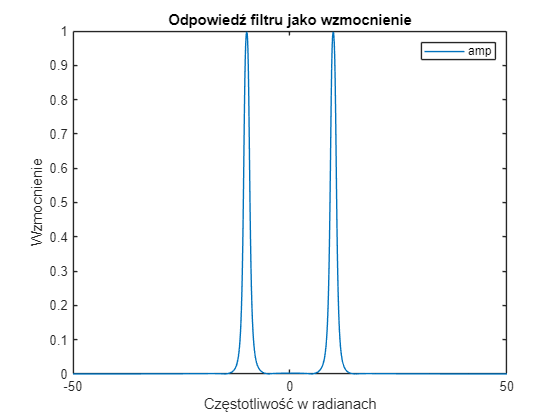

% Create plot of radianFreq and amp
h = plot(radianFreq,amp,"DisplayName","amp");

% Add xlabel, ylabel, title, and legend
xlabel("radianFreq")
ylabel("amp")
title("amp vs. radianFreq")
legend

title("Odpowiedź filtru jako wzmocnienie")

xlabel("Częstotliwość w radianach")
ylabel("Wzmocnienie")

ampdB=20*log10(amp);

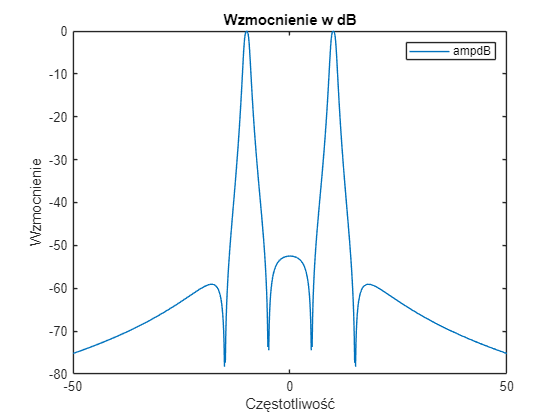

% Create plot of radianFreq and ampdB
h2 = plot(radianFreq,ampdB,"DisplayName","ampdB");

% Add xlabel, ylabel, title, and legend
xlabel("radianFreq")
ylabel("ampdB")
title("ampdB vs. radianFreq")
legend

title("Wzmocnienie w dB")
xlabel("Częstotliwość")
ylabel("Wzmocnienie")

phase = double(angle(H(radianFreq)));

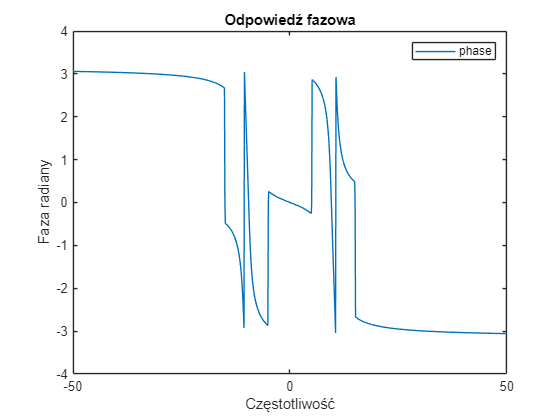

% Create plot of radianFreq and phase
h3 = plot(radianFreq,phase,"DisplayName","phase");

% Add xlabel, ylabel, title, and legend
xlabel("radianFreq")
ylabel("phase")
title("phase vs. radianFreq")
legend

title("Odpowiedź fazowa")
xlabel("Częstotliwość")
ylabel("Faza radiany")

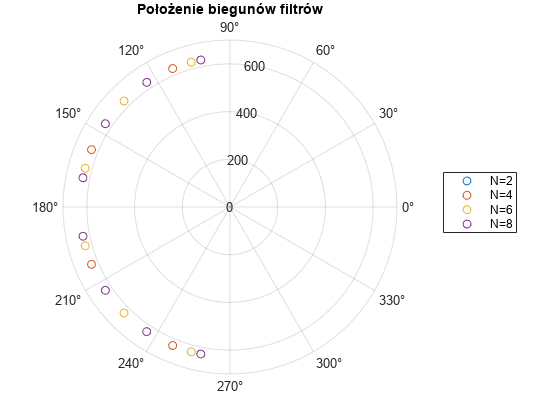

% Zad. 2
clear all;
% To można zmienić? Wpływa na wzmocnienie filtru
% Można też dać osobne dla każdego n=N
ba=1;
pulsacja_graniczna = 2*pi*100;
radianFreq=0:0.5:1.5*pulsacja_graniczna;

N=2:2:8;
filters={};
H=zeros(1,length(radianFreq));
for n=N
    p = pulsacja_graniczna*exp(1j*((pi/2)+(pi/(2*n))+(0:(n-1))*(pi/n)));
    p_rho=abs(p);
    p_theta=angle(p);
    for w = 1:length(radianFreq)
        H(w)=ba*((1j*radianFreq(w))/prod(1j*radianFreq(w)-p));
    end
    amp = 20*log10(abs(H));
    phase = angle(H);
    filters=[filters(:)',{{p_theta,p_rho,amp,phase}}];
end
figure
for i=1:4
    polarscatter(filters{i}{1},filters{i}{2});
    hold on;
end
hold off;

legend(["N=2","N=4","N=6","N=8"])
title("Położenie biegunów filtrów")

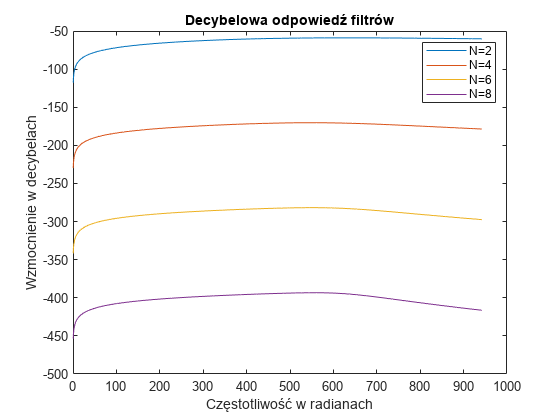

figure
for i=1:4
    plot(radianFreq,filters{i}{3});
    hold on;
end
hold off;

title("Decybelowa odpowiedź filtrów")
xlabel("Częstotliwość w radianach")
ylabel("Wzmocnienie w decybelach")
legend(["N=2","N=4","N=6","N=8"])

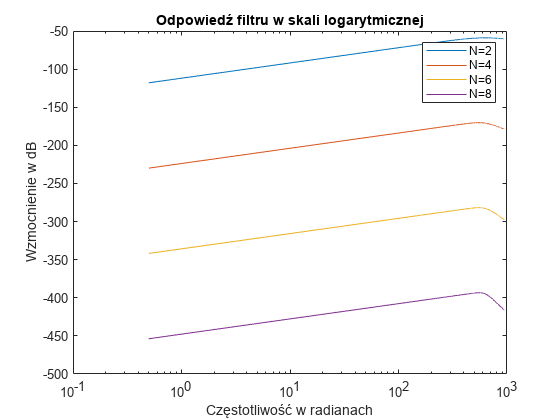


figure
for i=1:4
    semilogx(radianFreq,filters{i}{3});
    hold on;
end
hold off;
title("Odpowiedź filtru w skali logarytmicznej")
xlabel("Częstotliwość w radianach")
ylabel("Wzmocnienie w dB")
legend(["N=2","N=4","N=6","N=8"])

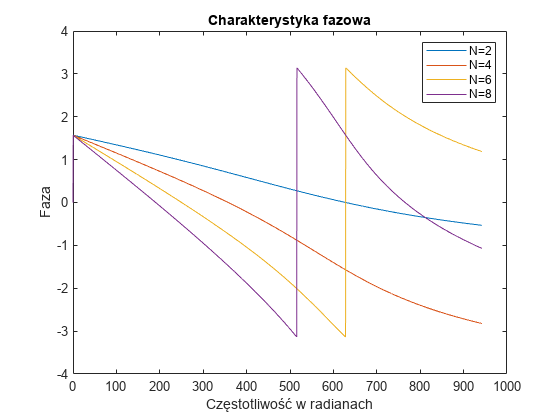


figure
for i=1:4
    plot(radianFreq,filters{i}{4});
    hold on;
end
hold off;

title("Charakterystyka fazowa")
legend(["N=2","N=4","N=6","N=8"])
xlabel("Częstotliwość w radianach")
ylabel("Faza")

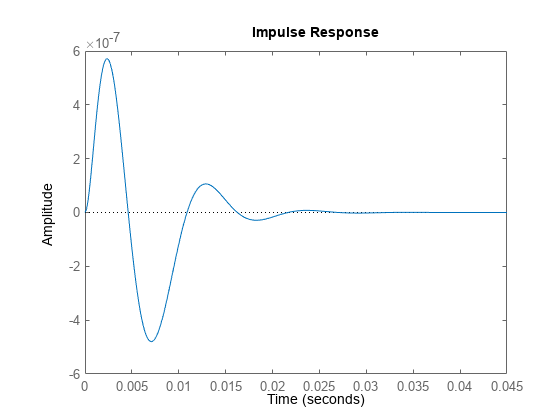


N=4;
p = pulsacja_graniczna*exp(1j*((pi/2)+(pi/(2*N))+(0:(N-1))*(pi/N)));
impulse(tf(poly(0),poly(p)));

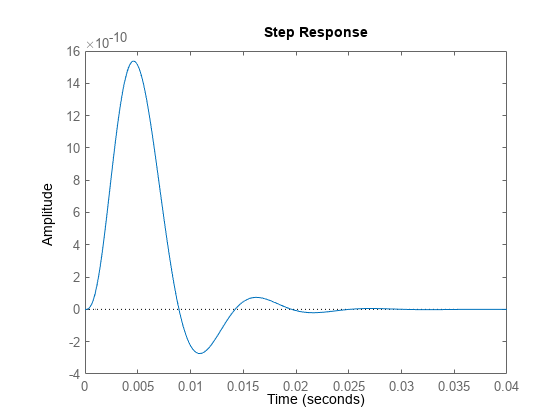

step(tf(poly(0),poly(p)));

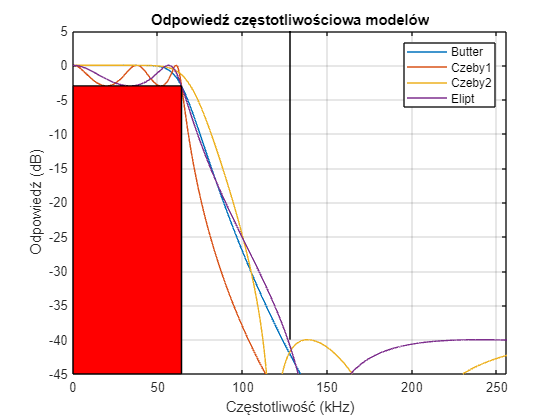

% Zad. 3
% zrobione wg. https://www.mathworks.com/help/signal/ref/freqs.html#mw_34730865-ac06-4487-864f-f6bc6ae1d533
clear all;
% cele:
% - maks tłumienie dla f>f_s/2
% - wzmocnienie = 1 dla f<f_s/2
% - minimalny rząd
% - zmiany tłumienia w paśmie f < 64 kHz nie większe niż 3 dB
% - tłumienie dla częstotliwości f_s/2 co najmniej 40 dB
sampling_freq = (256 * 1000);
cutoff = sampling_freq/2;
points = 4096; % mniej -> szybsze kalkulacje. Polecam wielokrotność 4
w = linspace(0,sampling_freq,points)*2*pi;

% Punkty i częstotliwości ustawione domyślnie są wystarczające dla
% spełnienia założeń. Dlatego częstotliwości odcięcia to 64kHz a nie 128
% kHz. Nie wspominając o tym że dla częstotliwości odcięcia 128kHz liczba
% punktów by dostać tłumienie >=40dB dla 128kHz (ta sama częstotliwość!)
% jest niebagatelna.

% Liczba punktów jest minimalna dla osiągnięcia krzywej która nie będzie
% tłumić za dużo dla <64kHz, ale "przejdzie" poniżej -40dB dla 128kHz
% Częstotliwość to tylko dopasowanie lewo/prawo

[zb,pb,kb] = butter(7,2*pi*1000*64,'s');
[bb,ab] = zp2tf(zb,pb,kb);
hb = freqs(bb,ab,w);

% 3 to zmiany tłumienia dla częstotliwości nie tłumionych
[z1,p1,k1]=cheby1(5,3,2*pi*1000*64,'s');
[b1,a1] = zp2tf(z1,p1,k1);
h1 = freqs(b1,a1,w);

% 40 to tłumienie w paśmie tłumienia
[z2,p2,k2]=cheby2(5,40,2*pi*1000*112,'s');
[b2,a2] = zp2tf(z2,p2,k2);
h2 = freqs(b2,a2,w);

% jak wyżej
[ze,pe,ke]=ellip(3,3,40,2*pi*1000*64,'s');
[be,ae] = zp2tf(ze,pe,ke);
he = freqs(be,ae,w);

% Poprawność filtrów - jak *nie* wyskakuje żadna wiadomość, to git. Polecam
% włączyć "Output on right", albo jescze lepiej "Hide code" przy testowaniu tego
if min(mag2db(abs(hb(1:points/4))))<-3
    "Filtr Butter ma zbyt duże zmiany tłumienia dla f<f_s/4"
end
if min(mag2db(abs(h1(1:points/4))))<-3
    "Filtr Czeby1 ma zbyt duże zmiany tłumienia dla f<f_s/4"
end
if min(mag2db(abs(h2(1:points/4))))<-3
    "Filtr Czeby2 ma zbyt duże zmiany tłumienia dla f<f_s/4"
end
if min(mag2db(abs(he(1:points/4))))<-3
    "Filtr Elipt ma zbyt duże zmiany tłumienia dla f<f_s/4"
end
if mag2db(abs(hb(points/2))) > -40
    "Filtr Butter nie tłumi wystarczająco dla f=f_s/2"
end
if mag2db(abs(h1(points/2))) > -40
    "Filtr Czeby1 nie tłumi wystarczająco dla f=f_s/2"
end
if mag2db(abs(h2(points/2))) > -40
    "Filtr Czeby2 nie tłumi wystarczająco dla f=f_s/2"
end
if mag2db(abs(he(points/2))) > -40
    "Filtr Elipt nie tłumi wystarczająco dla f=f_s/2"
end

% Odpowiedzi częstotliwościowe
plot([w; w; w; w]'/(2e3*pi), mag2db(abs([hb; h1; h2; he]')));
axis([0 256 -45 5])
grid;
% osie są w kHz a nie w Hz bo nie ma sensu mnożyć bytów
title("Odpowiedź częstotliwościowa modelów")
xlabel("Częstotliwość (kHz)");
ylabel("Odpowiedź (dB)");
rectangle('Position',[0 -45 64 42],'FaceColor','red','LineWidth',0.1,'EdgeColor','k','Visible',true)
line([128 128],[5 -40],'LineWidth',0.1,'Visible',true,'Color','k');

legend(["Butter" "Czeby1" "Czeby2" "Elipt"]);

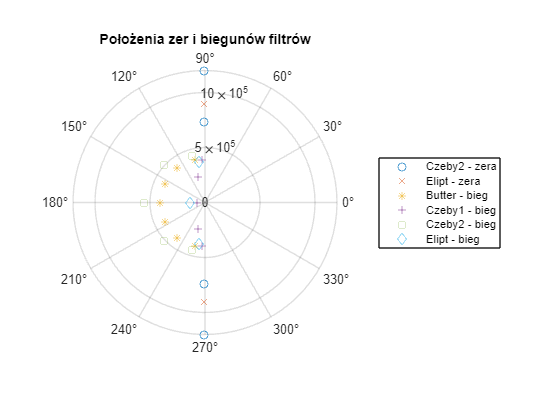


% Butter i Czeby nie zwraca zer. Kilka plotów dla różnych markerów -
% inaczej 'error using polarscatter - specify only one marker'.
polarscatter(angle(z2),abs(z2),'o');
hold on;
polarscatter(angle(ze),abs(ze),'x');
polarscatter(angle(pb),abs(pb),'*');
polarscatter(angle(p1),abs(p1),'+');
polarscatter(angle(p2),abs(p2),'square');
polarscatter(angle(pe),abs(pe),'diamond');
hold off;
title("Położenia zer i biegunów filtrów");
legend(["Czeby2 - zera" "Elipt - zera" "Butter - bieg" "Czeby1 - bieg" "Czeby2 - bieg" "Elipt - bieg"]);

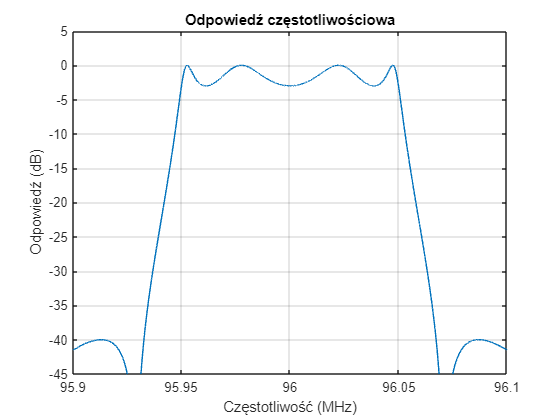

% Zad. 4
clear all;
points=4096;
% Model dostaje epilepsji powyżej 4 punktów, dlatego jest zablokowane na 4
N=4;
mid_freq_unscaled = 96;
mid_freq = 2*pi*1e6*mid_freq_unscaled;
tollerance_unscaled = 50;
tollerance = 2*pi*1e3*tollerance_unscaled;
w = linspace(mid_freq-2*tollerance,mid_freq+2*tollerance,points);
[ze,pe,ke]=ellip(N,3,40,[mid_freq-tollerance,mid_freq+tollerance],'s');
[be,ae] = zp2tf(ze,pe,ke);
he=freqs(be,ae,w);
% Odpowiedzi częstotliwościowe
plot(w/(2e6*pi), mag2db(abs(he)));
axis([mid_freq_unscaled-2*tollerance_unscaled/1e3 mid_freq_unscaled+2*tollerance_unscaled/1e3 -45 5])
grid;
% osie są w kHz a nie w Hz bo nie ma sensu mnożyć bytów
title("Odpowiedź częstotliwościowa")
xlabel("Częstotliwość (MHz)");
ylabel("Odpowiedź (dB)");